## IE311 - Aula Prática 3

## Compressão em Alcance

**Exemplo 1**

A largura do pulso após a compressão em alcance depende da banda do pulso modulado em frequência, e não de sua duração.

*PSLR = p*eak to sidelobe ratio*

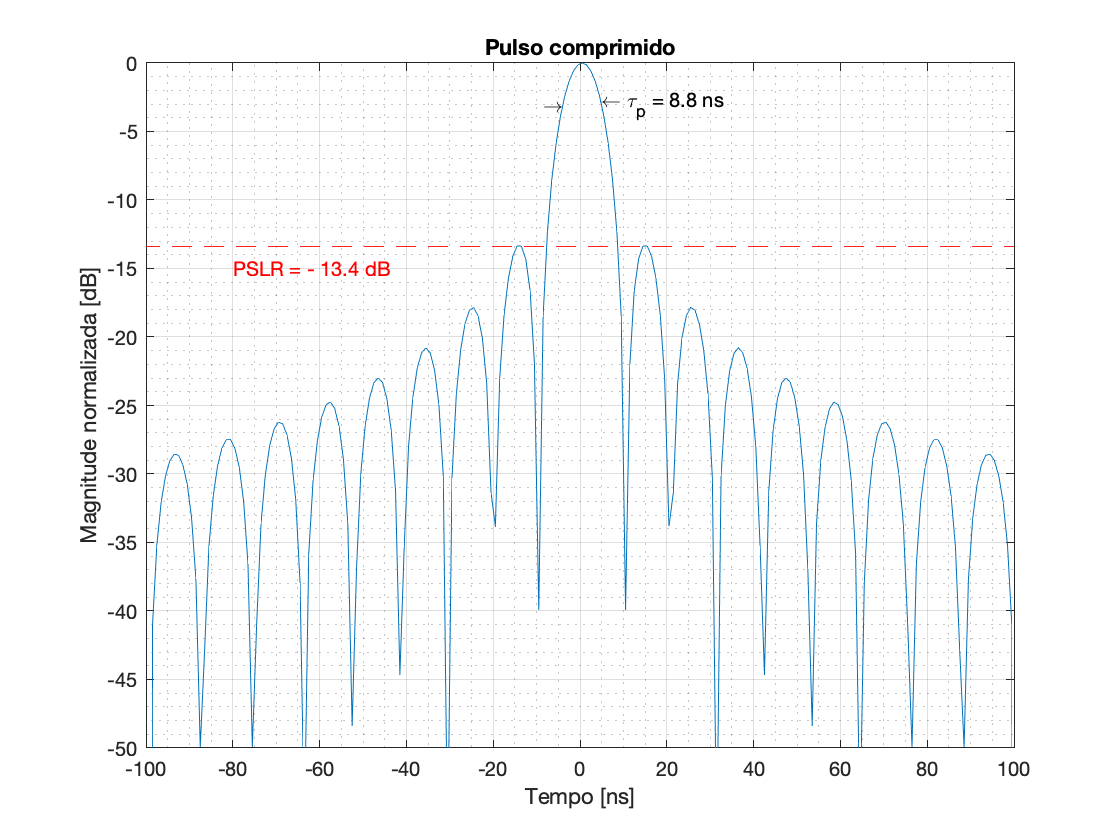

tau = 1e-6;   % Duração do pulso
BW = 100e6;    % Banda do pulso   
samplingRate = 1e9;         % Taxa de amostragem (superamostragem)
threshold = -3;             % Limiar (dB) para o cálculo da largura de pulso

[t,signalDB,t1,t2] = exPulse(tau,BW,samplingRate,threshold,'none');

figure
plot(t/1e-9,signalDB,[-100 100],[-13.4 -13.4],'r--')
xlabel('Tempo [ns]')
ylabel('Magnitude normalizada [dB]')
title('Pulso comprimido')

text(-80,-15,'PSLR = - 13.4 dB','Color','r')
text(t1*1e9,threshold,'\rightarrow','HorizontalAlignment','right')
str = ['\leftarrow \tau_{p} = ',num2str((t2-t1)*1e9,'%.1f'),' ns'];
text(t2*1e9,threshold,str)

xlim([-100 100])
ylim([-50 0])
grid on
grid minor

**Exemplo 2**

Mostra o efeito sobre a esolução (largura do pulso comprimido) e o PSLR ao aplicarmos uma função de janelamento de hamming no sinal de referência.

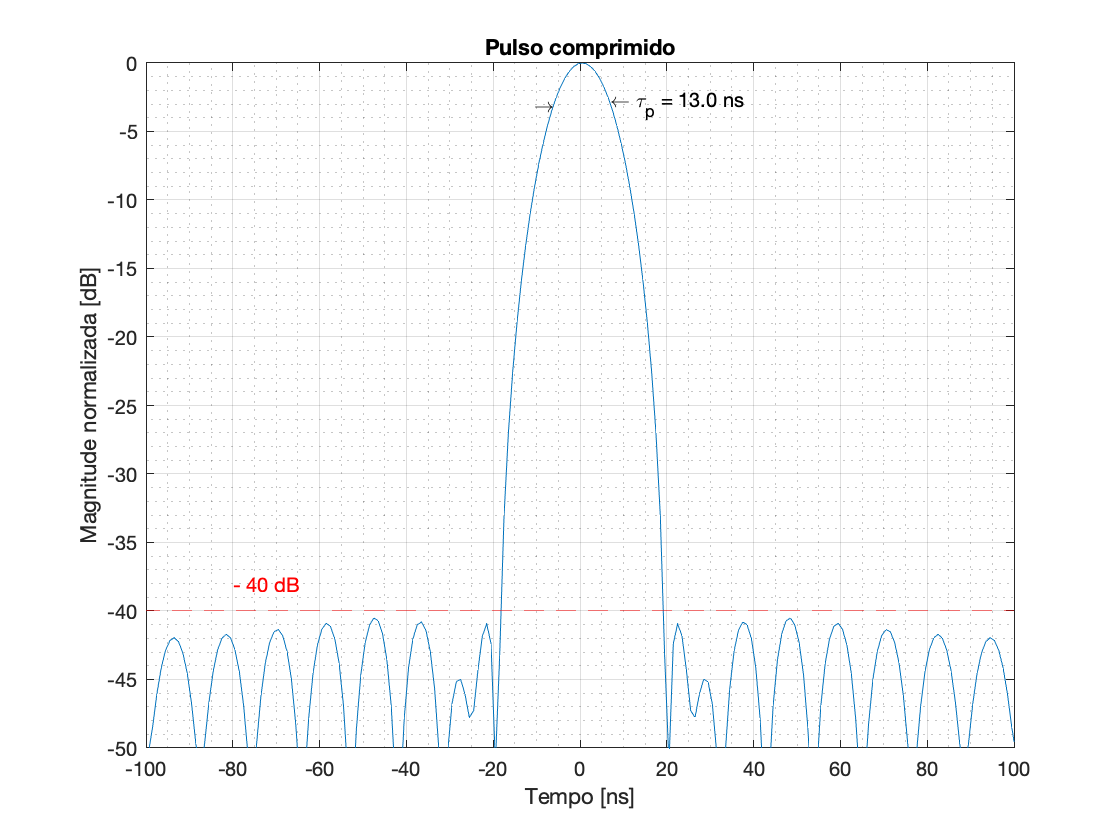

tau = 1e-6;   % Duração do pulso
BW = 100e6;    % Banda do pulso
samplingRate = 1e9;         % Taxa de amostragem (superamostragem)
threshold = -3;             % Limiar (dB) para o cálculo da largura de pulso

[t,signalDB,t1,t2] = exPulse(tau,BW,samplingRate,threshold,'hamming');

plot(t/1e-9,signalDB,[-100 100],[-40 -40],'r--')
xlabel('Tempo [ns]')
ylabel('Magnitude normalizada [dB]')
title('Pulso comprimido')

text(-80,-38,'- 40 dB','Color','r')
text(t1*1e9,threshold,'\rightarrow','HorizontalAlignment','right')
str = ['\leftarrow \tau_{p} = ',num2str((t2-t1)*1e9,'%.1f'),' ns'];
text(t2*1e9,threshold,str)

xlim([-100 100])
ylim([-50 0])
grid on
grid minor

**Exemplo 3**

No caso de presença de ruído no sinal de retorno, a compressão em alcance reduz o desvio padrão do ruído por um fator de $\sqrt{M}$, em que $M$é a largura da janela do pulso em número de amostras. 

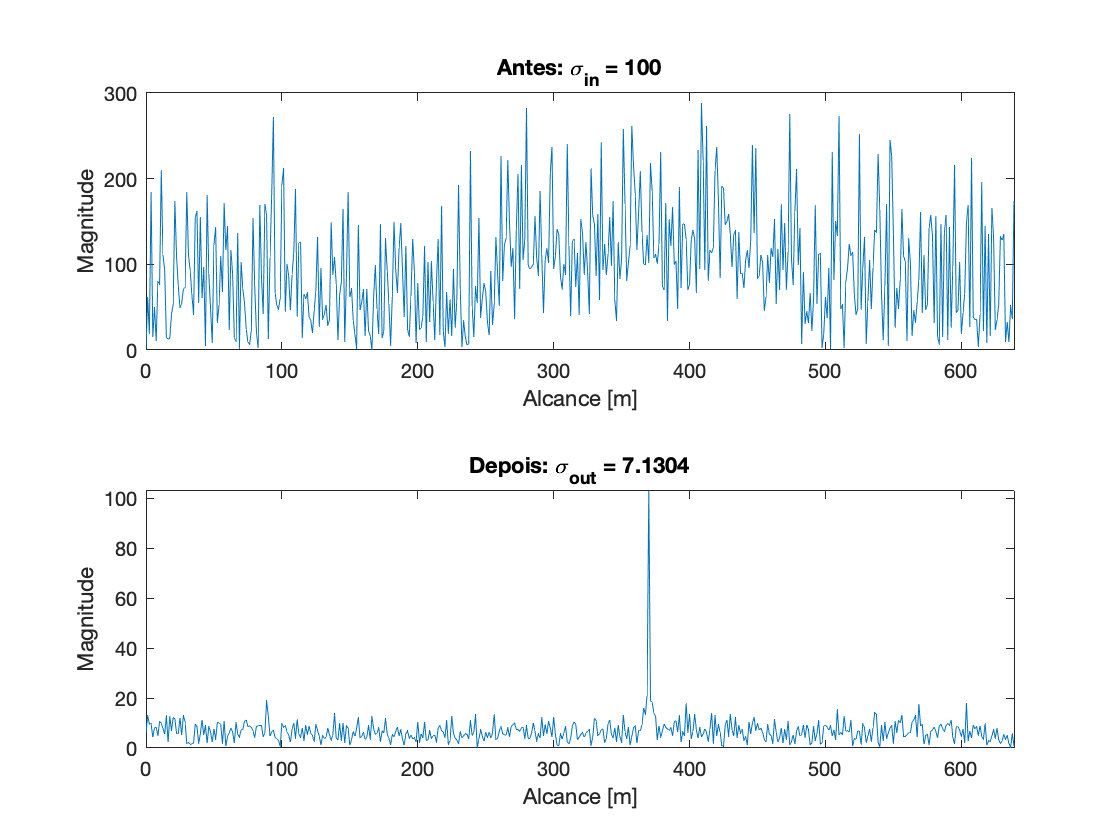

tau = 1.5e-6; % Duração do pulso
BW = 100e6;  % Banda do pulso
samplingRate = 120e6;     % Taxa de amostragem
lambda = 0.056;           % Comprimento de onda
targetRange = 370;        % Distância do radar até o alvo
targetRCS = 100;          % Taxa de retorno do alvo
N = 512;                  % Número de amostras em alcance

sigmaIn = 100;  % Desvio padrão do ruído

[rangeAxis,beforeCompression,afterCompression,sigmaOut] = exRangeLine(...
    targetRange,targetRCS,N,lambda,samplingRate,tau,BW,sigmaIn,'none');

subplot(2,1,1)
plot(rangeAxis,abs(beforeCompression))
title(['Antes: \sigma_{in} = ',num2str(sigmaIn)])
xlabel('Alcance [m]')
ylabel('Magnitude')
xlim([0 rangeAxis(end)])

subplot(2,1,2)
plot(rangeAxis,abs(afterCompression))
title({'',['Depois: \sigma_{out} = ',num2str(sigmaOut)]})
xlabel('Alcance [m]')
ylabel('Magnitude')
xlim([0 rangeAxis(end)])


(sigmaIn/sigmaOut)^2

ans = 196.6832

**Exemplo 4**

Caso em que há dois alvos bem próximos um do outro.

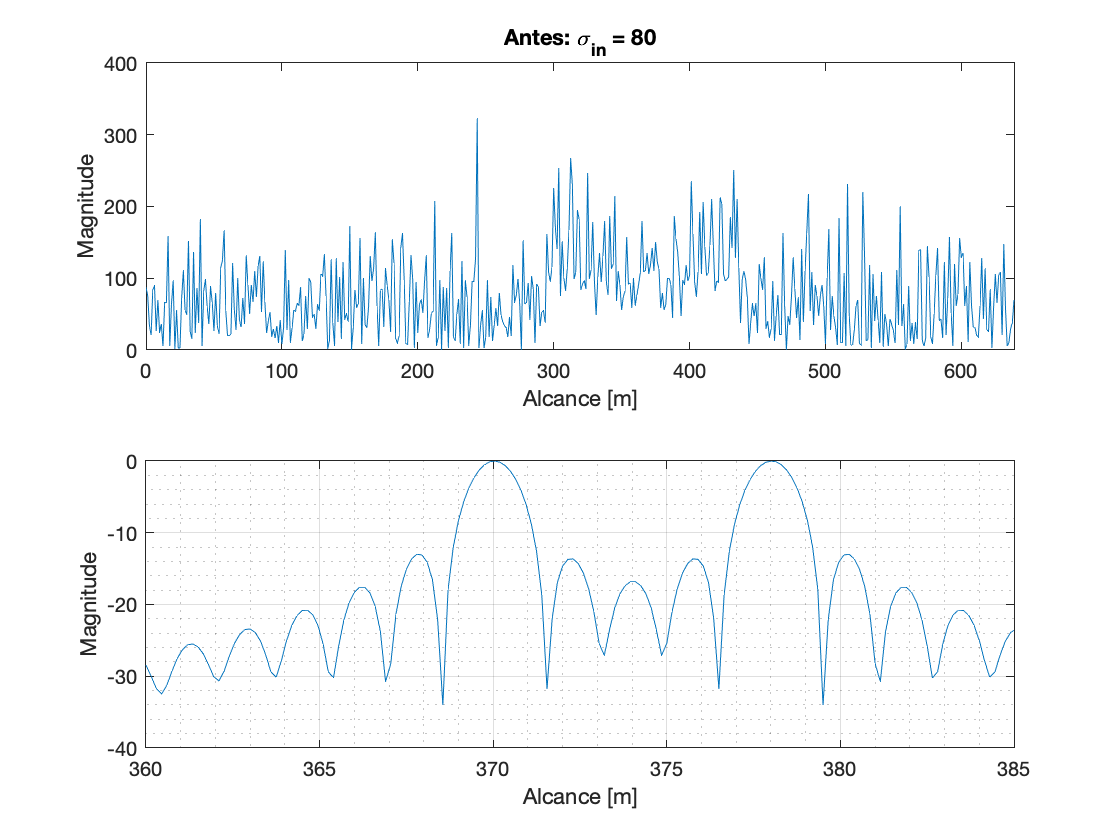

BW = 100e6;     % Banda do pulso
window = 'none'; % Tipo de janelamento

% Diferença de alcance entre dois alvos próximos
diffRange =8;
targetRange = [370 370 + diffRange];  

tau = 1e-6;               % Duração do pulso
samplingRate = 1e9;       % Taxa de amostragem (superamostragem)
lambda = 0.056;           % Comprimento de onda
targetRCS = [100 100];    % Taxa de retorno do alvo
N = 4096;                 % Número de amostras em alcance

[rangeAxis,~,compressedSignal,~] = exRangeLine(...
    targetRange,targetRCS,N,lambda,samplingRate,tau,BW,0,window);

signalDB = 20*log10(abs(compressedSignal/max(compressedSignal)));

plot(rangeAxis,signalDB)
xlabel('Alcance [m]')
ylabel('Magnitude')
xlim([360 385])
ylim([-40 0])
grid on
grid minor

function [t,signalDB,t1,t2] = exPulse(tau,BW,samplingRate,threshold,window)
% Pulso modulado em frequência --------------------------------------------
M = fix(tau*samplingRate);
m = -(M-1)/2:(M-1)/2;
t = m/samplingRate;
kappa = BW/tau;
chirpPhase = pi*kappa*t.^2;
chirp = exp(1i*chirpPhase);
% -------------------------------------------------------------------------
% Pulso comprimido --------------------------------------------------------
switch window
    case 'none'
    reference = circshift(chirp,-floor(M/2));
case 'hamming'
    hamming = 0.54 + 0.46*cos(2*pi*m/(M-1));
    reference = circshift(chirp.*hamming,-floor(M/2));
end
compressedPulse = ifft(fft(chirp).*conj(fft(reference)));
signalDB = 20*log10(abs(compressedPulse/max(compressedPulse)));
% -------------------------------------------------------------------------
% Largura do pulso --> Encontra os pontos mais próximos, depois usa 
% interpolação para encontrar os instantes em que a curva cruza o limiar
[~,m1]=min(abs(signalDB(1:M/2)-threshold));
[~,m2]=min(abs(signalDB(M/2:end)-threshold));
m2 = m2 + M/2 -1;
t1 = interp1(signalDB(m1-1:m1+1),t(m1-1:m1+1),threshold);
t2 = interp1(signalDB(m2-1:m2+1),t(m2-1:m2+1),threshold);
% -------------------------------------------------------------------------
end

% =========================================================================
function [rngAxis,beforeCompr,afterCompr,sigmaOut] = exRangeLine(range,...
    RCS,N,lambda,fs,tau,BW,sigmaIn,window)

c = 3e8;    % Velocidade da luz

% Linha de alcance com impulso na amostra correspondente ao alvo ----------
phi = -4*pi*range/lambda;
deltaRng = c/fs/2;
rngBin = round(range/deltaRng)+1;
rngLine0 = zeros(1,N);
rngLine0(rngBin) = RCS.*exp(1i*phi);
% -------------------------------------------------------------------------
% Pulso modulado em frequência --------------------------------------------
M = fix(tau*fs);
m = -(M-1)/2:(M-1)/2;
t = m/fs;
kappa = BW/tau;
chirpPhase = pi*kappa*t.^2;
chirp = exp(1i*chirpPhase);
% -------------------------------------------------------------------------
% Sinal de retorno antes da copressão em alcance --------------------------
beforeCompr = conv(rngLine0,chirp,'same');
beforeCompr = beforeCompr + sigmaIn*randn(1,N);
% -------------------------------------------------------------------------
% Sinal após a copressão em alcance ---------------------------------------
switch window
    case 'none'
    reference = circshift([chirp,zeros(1,N-M)],-fix(M/2))/M;
case 'hamming'
    hamming = 0.54 + 0.46*cos(2*pi*m/(M-1));
    reference = circshift([chirp.*hamming,zeros(1,N-M)],-floor(M/2))*2/M;
end
afterCompr = ifft(fft(beforeCompr).*conj(fft(reference)));
% -------------------------------------------------------------------------
sigmaOut = std(afterCompr(1:rngBin-20)); % Desvio padrão após compressão
rngAxis = (0:N-1)*deltaRng;
end